Very useful: put the calculations in the symbolic calculator in reversed order, so that you don't have long incomprehensible expressions

syms s1 s2 c1 c2 c3 s3 L N M px py pz real

A = [L + N*c3*c2 , -N*c3*s2; N*c3*s2 , L+N*c3*c2];
det(A) %this determinant has to be non null

$$ans = L^{2}+2\,L\,N\,c_{2}\,c_{3}+N^{2}\,{c_{2}}^{2}\,{c_{3}}^{2}+N^{2}\,{c_{3}}^{2}\,{s_{2}}^{2}$$

b = [px;py];
c1s1 = A \ b

$$c1s1 = \begin{array}{l} \left(\begin{array}{c} \frac{L\,\mathrm{px}+N\,c_{2}\,c_{3}\,\mathrm{px}+N\,c_{3}\,\mathrm{py}\,s_{2}}{\sigma_{1}}\\ \frac{L\,\mathrm{py}+N\,c_{2}\,c_{3}\,\mathrm{py}-N\,c_{3}\,\mathrm{px}\,s_{2}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L^{2}+2\,L\,N\,c_{2}\,c_{3}+N^{2}\,{c_{2}}^{2}\,{c_{3}}^{2}+N^{2}\,{c_{3}}^{2}\,{s_{2}}^{2} \end{array}$$

q1 = atan2(c1s1(2),c1s1(1))

$$q1 = \begin{array}{l} \text{atan2}\left(\frac{L\,\mathrm{py}+N\,c_{2}\,c_{3}\,\mathrm{py}-N\,c_{3}\,\mathrm{px}\,s_{2}}{\sigma_{1}},\frac{L\,\mathrm{px}+N\,c_{2}\,c_{3}\,\mathrm{px}+N\,c_{3}\,\mathrm{py}\,s_{2}}{\sigma_{1}}\right)\\ \mathrm{where}\\ \sigma_{1}=L^{2}+2\,L\,N\,c_{2}\,c_{3}+N^{2}\,{c_{2}}^{2}\,{c_{3}}^{2}+N^{2}\,{c_{3}}^{2}\,{s_{2}}^{2} \end{array}$$

c2 = (px^2+py^2-L^2-N^2*c3^2)/(2*L*N*c3);
s2 = -sqrt(1-c2^2);
q2 = atan2(s2,c2)

$$q2 = \text{atan2}\left(-2\,\sqrt{1-\frac{{\left(L^{2}+N^{2}\,{c_{3}}^{2}-{\mathrm{px}}^{2}-{\mathrm{py}}^{2}\right)}^{2}}{4\,L^{2}\,N^{2}\,{c_{3}}^{2}}},-\frac{L^{2}+N^{2}\,{c_{3}}^{2}-{\mathrm{px}}^{2}-{\mathrm{py}}^{2}}{L\,N\,c_{3}}\right)$$

s3 = (pz-M)/N;
c3 = -sqrt(1-s3^2);
q3 = atan2(s3,c3)

$$q3 = \text{atan2}\left(-\frac{M-\mathrm{pz}}{N},-\sqrt{1-\frac{{\left(M-\mathrm{pz}\right)}^{2}}{N^{2}}}\right)$$

q2 = subs(q2); q1 = subs(q1);
L = 0.5; M = 0.5; N = 0.5; px = 0.3; py = -0.3; pz = 0.7;

q3 = eval(subs(q3))

q3 = 2.7301

c3 = cos(q3); s3 = sin(q3);
q2 = eval(subs(q2))

q2 = -0.9135

c2 = cos(q2); s2 = sin(q2);
q1 = eval(subs(q1))

q1 = -1.8110

syms q1 q2 q3 real

fr = [cos(q1) + cos(q1+q2)*cos(q3); sin(q1) + sin(q1+q2)*cos(q3); 1+sin(q3)]

$$fr = \left(\begin{array}{c} \cos\left(q_{1}\right)+\cos\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}\right)\\ \sin\left(q_{1}\right)+\sin\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}\right)\\ \sin\left(q_{3}\right)+1 \end{array}\right)$$

qs = [-pi/4, pi/4, pi/4];
qg = [0, 0, pi/4];
T = 2;
pdot = [1,-1,0]';
J = jacobian(fr,[q1,q2,q3])

$$J = \left(\begin{array}{ccc} -\sin\left(q_{1}\right)-\sin\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}\right) & -\sin\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}\right) & -\cos\left(q_{1}+q_{2}\right)\,\sin\left(q_{3}\right)\\ \cos\left(q_{1}\right)+\cos\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}\right) & \cos\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}\right) & -\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{3}\right)\\ 0 & 0 & \cos\left(q_{3}\right) \end{array}\right)$$

J = subs(J,[q1,q2,q3],qs)/2

$$J = \left(\begin{array}{ccc} \frac{\sqrt{2}}{4} & 0 & -\frac{\sqrt{2}}{4}\\ \frac{\sqrt{2}}{2} & \frac{\sqrt{2}}{4} & 0\\ 0 & 0 & \frac{\sqrt{2}}{4} \end{array}\right)$$

qdot =  J \ pdot

$$qdot = \left(\begin{array}{c} 2\,\sqrt{2}\\ -6\,\sqrt{2}\\ 0 \end{array}\right)$$

deltaq = [qg - qs]'

deltaq =     0.7854
   -0.7854
         0


syms a3 a4 a5 real

i = 1;
v0 = eval(qdot(i)*T/deltaq(i));
A = [1 1 1; 3 4 5; 6 12 20];
b = [1-v0 ; -v0; 0];

a = A \ b

a =   -33.2152
   42.6202
  -15.6076


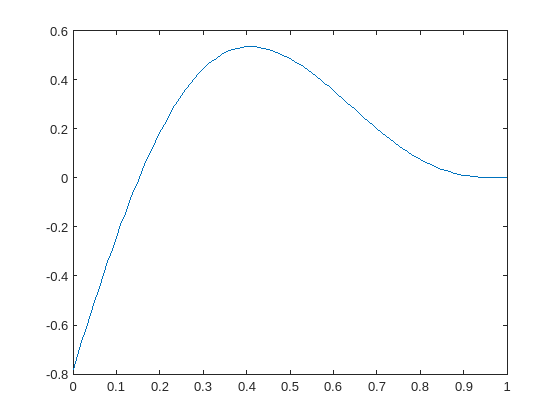

tau = 0:0.01:1;
q = -0.78 + 0.78*(v0*tau + a(1)*tau.^3 + a(2)*tau.^4 + a(3)*tau.^5);
plot(tau,q)

Ex 3

clear;
syms q1 q2 q3 real

L = 0.5; M = 0.5; N = 0.5;

fr = [L*cos(q1) + N*cos(q1+q2)*cos(q3); L*sin(q1) + N*sin(q1+q2)*cos(q3); M+N*sin(q3)]

$$fr = \left(\begin{array}{c} \frac{\cos\left(q_{1}\right)}{2}+\frac{\cos\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}\right)}{2}\\ \frac{\sin\left(q_{1}\right)}{2}+\frac{\sin\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}\right)}{2}\\ \frac{\sin\left(q_{3}\right)}{2}+\frac{1}{2} \end{array}\right)$$

Jsym = jacobian(fr,[q1,q2,q3])

$$Jsym = \begin{array}{l} \left(\begin{array}{ccc} -\frac{\sin\left(q_{1}\right)}{2}-\sigma_{1} & -\sigma_{1} & -\frac{\cos\left(q_{1}+q_{2}\right)\,\sin\left(q_{3}\right)}{2}\\ \frac{\cos\left(q_{1}\right)}{2}+\sigma_{2} & \sigma_{2} & -\frac{\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{3}\right)}{2}\\ 0 & 0 & \frac{\cos\left(q_{3}\right)}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sin\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}\right)}{2}\\ \sigma_{2}=\frac{\cos\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}\right)}{2} \end{array}$$

pd = [0.3;-0.3;0.7];
q = [pi/4;pi/4;pi];
for i=1:5
    fprintf("Iteration%d",i)
    error = eval(pd - subs(fr,[q1;q2;q3],q));
    J = subs(Jsym,[q1;q2;q3],q);
    q = eval(q +  J \ error)
    error = norm(error);
end

Iteration1

q =     0.3511
    0.8055
    2.7416


Iteration2

q =     0.2347
    0.9099
    2.7301


Iteration3

q =     0.2403
    0.9134
    2.7301


Iteration4

q =     0.2402
    0.9135
    2.7301


Iteration5

q =     0.2402
    0.9135
    2.7301
